clc
clear all
syms q1 q2 dq1 dq2 ddq1 ddq2 m1 m2 I1 I2 L g real

## Jacobian

O0=[0 0 0]';
Oc1=[0 0 0]';
Oc2=[(q2+L)*cos(q1) (q2+L)*sin(q1) 0]'

$$Oc2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(L+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(L+q_{2}\right)\\ 0 \end{array}\right)$$

zeros=[0 0 0]';
R = [cos(q1) -sin(q1) 0;sin(q1) cos(q1) 0;0 0 1];
z0=[0 0 1]';
z1=R(:,1);
Jw1=[z0 zeros]

Jw1 =      0     0
     0     0
     1     0


Jv1=[zeros zeros]

Jv1 =      0     0
     0     0
     0     0


Jv2=[cross(z0,Oc2-O0),z1]

$$Jv2 = \left(\begin{array}{cc} -\sin\left(q_{1}\right)\,\left(L+q_{2}\right) & \cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\left(L+q_{2}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

Jw2=[z0,zeros]

Jw2 =      0     0
     0     0
     1     0


## Euler-Lagrange Method

q=[q1;q2];
R = [cos(q1) -sin(q1) 0;sin(q1) cos(q1) 0;0 0 1];
D1=m1*Jv1'*Jv1 + Jw1'*R*I1*R'*Jw1;
D2=m2*Jv2'*Jv2 + Jw2'*R*I2*R'*Jw2;
D=D1+D2;
D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,L^{2}+2\,m_{2}\,L\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

P=(m2)*g*((q2+L)*sin(q1))

$$P = g\,m_{2}\,\sin\left(q_{1}\right)\,\left(L+q_{2}\right)$$

G1=diff(P,q1);
G2=diff(P,q2);
G=[G1;G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(L+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

dq = [dq1; dq2];
ddq = [ddq1; ddq2];
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,m_{2}\,\left(L+q_{2}\right) & {\mathrm{dq}}_{1}\,m_{2}\,\left(L+q_{2}\right)\\ {\mathrm{dq}}_{1}\,m_{2}\,\left(L+q_{2}\right) & 0 \end{array}\right)$$

tor = D*ddq+C*dq+G

$$tor = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(m_{2}\,L^{2}+2\,m_{2}\,L\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(L+q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(L+q_{2}\right)\\ m_{2}\,\left(L+q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

tor=simplify(tor);
D(q1,q2) = subs(D,{m1, m2, I1, I2,L },{2 2 1 2 0.2});
C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2,L },{2 2 1 2 0.2});
G(q1,q2) = subs(G ,{m1, m2, I1, I2,L,g},{2 2 1 2 0.2 9.81});


## inverse dynamics

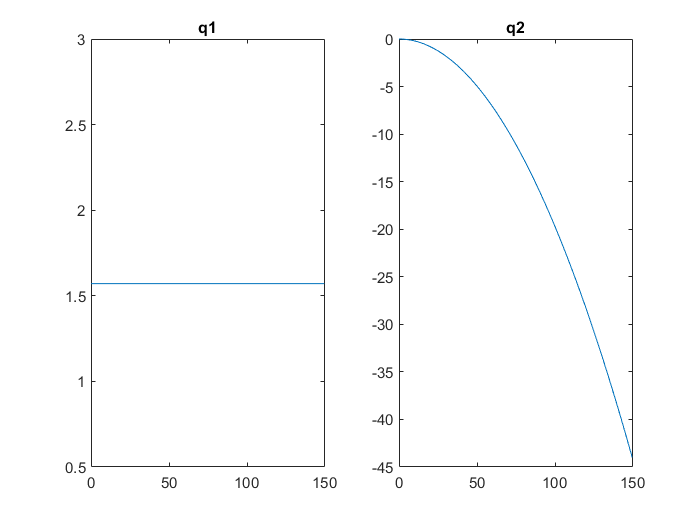

% input U to get the changes of q,dq,ddq vs time
% at this configuration when q=[pi/2 0] , q1 should stay fixed vs time 
% and q2 should keep decreasing because of gravity 
q1_0 = pi/2;
q2_0 = 0;
dq1_0 = 0;
dq2_0 = 0;
dt=0.01;
U = [0;0];
n=300;
for i = 1:n
q1p(i)=q1_0;
q2p(i)=q2_0;
dq1p(i)=dq1_0;
dq2p(i)=dq2_0;
ddq = inv(D(q1_0, q2_0))*(U-C(q1_0, q2_0,dq1_0,dq2_0)-G(q1_0,q2_0));
ddq1p(i)=ddq(1);
ddq2p(i)=ddq(2);
dq1_0=dq1p(i) + double(ddq(1)*dt);
dq2_0=dq2p(i) + double(ddq(2)*dt);
q1_0 = q1p(i) + dq1_0*dt;
q2_0 = q2p(i) + dq2_0*dt;
end
t = 0:0.5:(0.5*(n-1));
figure
subplot(1,2,1)
plot(t,q1p)
title('q1')
subplot(1,2,2)
plot(t,q2p)
title('q2')

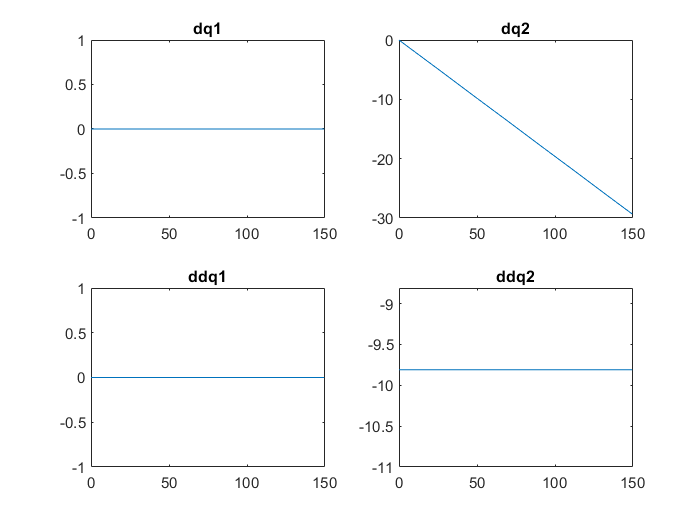

figure
subplot(2,2,1)
plot(t,dq1p)
title('dq1')
subplot(2,2,2)
plot(t,dq2p)
title('dq2')
subplot(2,2,3)
plot(t,ddq1p)
title('ddq1')
subplot(2,2,4)
plot(t,ddq2p)
title('ddq2')

## coriolis

function C=Coriolis(D,q,dq,n)
sym C;
for k=1:n
    for j=1:n
        C(k,j)=sym(0);
        for i=1:n
            c_ijk=(1/2)*(diff(D(k,j),q(i))+diff(D(k,i),q(j))+diff(D(i,j),q(k)));
            C(k,j)=C(k,j)+c_ijk*dq(i);
        end
    end
end
end




